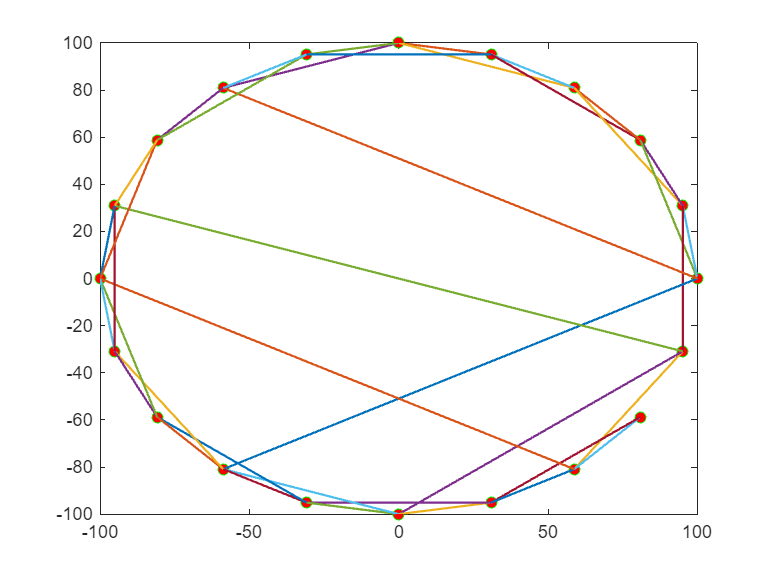

N=20;K=4;p=0.2; %N为网络节点总数,K为邻域节点个数 p为重连概率
t=0:2*pi/N:2*pi-2*pi/N;  %生成最近邻耦合网络个节点坐标的参数方程的角度
x=100*sin(t);
y=100*cos(t);
plot(x,y,'ro','MarkerEdgeColor','g','MarkerFaceColor','r','MarkerSize',6);
hold on;
A=zeros(N); %邻接矩阵初始化
for i=1:N %循环构造最临近K耦合网络的邻接矩阵
    for j=i+1:i+K/2
        jj=(j<=N)*j+(j>N)*mod(j,N); %如果j超过N要除以N的余数
        A(i,jj)=1;
        A(jj,i)=1;
    end
end
for i=1:N %随机重连
    for j=i+1:i+K/2
        jj=(j<=N)*j+(j>N)*mod(j,N);
        ChangeV=randi([1,N]); %产生随机整数
        if rand<=p && A(i,ChangeV)==0 && i~=ChangeV
            A(i,jj)=0; %删除原边
            A(jj,i)=0;
            A(i,ChangeV)=1; %重连新边
            A(ChangeV,i)=1;
        end
    end
end
for i=1:N-1
    for j=i+1:N
        if A(i,j)~=0
            plot([x(i),x(j)],[y(i),y(j)],'LineWidth',1.2);
        end
    end
end

Matlab_to_Pajek(A)

str = 'Pajek_data1.net'

function Matlab_to_Pajek(A,k)
    if nargin==1
       str='Pajek_data1.net'
    else
       str=['Pajek_data',int2str(k),'.net']
    end
    n=length(A);
    v=1:n;
    fid=fopen(str,'w'); %创建文本文件
    fprintf(fid,'%s%d\n','*Vertices ',n); %写入字符串换行
    for i=1:n
        fprintf(fid,'%d ',v(i)); %写入节点编号
        fprintf(fid,'"%d"\n',v(i)); %写入双引号换行
    end
    fprintf(fid,'%s\n%s\n','*Arcs','*Edges'); %写入两个字符串
    A=tril(A); %下三角元素
    [u,v]=find(A);
    n=length(u); %非零元素个数
    for i=1:n
        fprintf(fid,' %d %d 1\n',u(i),v(i)); %写入边信息
    end
    fclose(fid);
end

N=20;K=4;p=0.2;
t=0:2*pi/N:2*pi-2*pi/N;
x=100*sin(t);
y=100*cos(t);
plot(x,y,'ro','MarkerEdgeColor','g','MarkerFaceColor','r','MarkerSize',6);
hold on;

A=zeros(N);
for i=1:N
    for j=i+1:i+K/2
        jj=(j<=N)*j+(j>N)*mod(j,N);
        A(i,jj)=1;
        A(jj,i)=1;
    end
end
for i=1:N
    for j=i+1:i+K/2
        source=randi(N); %随机源节点
        target=randi(N); %随机目标节点
        while target==source %自环
            target=randi(N); 
        end
        while A(source, target) == 1 %存在边
            source = randi(N);
            target = randi(N);
        end
        if rand<p
           A(source,target)=1; %加边
           A(target,source)=1;
        end
    end
end
for u=1:N-1
    for j=i+1:N
        if A(i,j)~=0
            plot([x(i),x(j)],[y(i),y(j)],'LineWidth',1.2);
        end
    end
end
Matlab_to_Pajek(A,2)

str = 'Pajek_data2.net'